We extract FRC of a three DOFs model with 1:1:1 internal resonance


$$\ddot{x}_1+x_1+\epsilon c_1\dot{x}_1+ K(x-y)^3=\epsilon f_1\cos\Omega t,\\
\ddot{x}_2+x_2+\epsilon c_2\dot{x}_2+ K[(y-x)^3+(y-z)^3]=\epsilon f_2\cos\Omega t,\\
\ddot{x}_3+x_3+\epsilon c_3\dot{x}_3+ K(z-y)^3=\epsilon f_3\cos\Omega t.$$


clear all, close all, clc

## Example Setup

c1 = 1e-1;
c2 = 2e-1;
c3 = 3e-1;
K = 0.2; 
epsilon = 5e-3;
[mass,damp,stiff,fnl,fext]=build_model(c1,c2,c3,K,epsilon);

## Dynamical System Setup

DS = DynamicalSystem();
set(DS,'M',mass,'C',damp,'K',stiff,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

% Forcing
kappas = [1; -1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);

**Linear Modal analysis**

startMD = tic;
[V,D,W] = DS.linear_spectral_analysis();


 The first 6 eigenvalues are given as 
  -0.0002 + 1.0000i
  -0.0002 - 1.0000i
  -0.0005 + 1.0000i
  -0.0005 - 1.0000i
  -0.0008 + 1.0000i
  -0.0008 - 1.0000i



timings.MD = toc(startMD);

## 6D SSM based computation

**1:1 internal resonance**

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
resonant_modes = [1 2 3 4 5 6];
mFreq  = [1 1 1];
order = 3;
outdof = [1 2 3];

Using ep toolbox - polar (failed when $\rho_3\to 0$

set(S.Options, 'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'method','continuation ep')
set(S.FRCOptions, 'outdof',outdof)
set(S.FRCOptions, 'initialSolver', 'fsolve');
set(S.contOptions,'PtMX',250);

freqRange = [0.995 1.016];
% call extract_FRC to calculate the FRC
FRC = S.extract_FRC('freq',freqRange,order);

% call FRC_cont_ep to calculate the FRC
startep = tic;
FRC_ep_polar = S.FRC_cont_ep('isol_polar',resonant_modes, order, mFreq, 'freq', freqRange);

sigma_out = 0
(near) inner resonance detected for the following combination of master eigenvalues
     1     0     0     0     1     0
     0     0     0     0     2     1
     0     0     0     1     2     0
     0     0     1     0     1     1
     0     0     1     1     1     0
     0     0     2     0     0     1
     0     0     2     1     0     0
     0     1     0     0     2     0
     0     1     1     0     1     0
     0     1     2     0     0     0
     1     0     0     0     1     1
     1     0     0     1     1     0
     1     0     1     0     0     1
     1     0     1     1     0     0
     1     1     0     0     1     0
     1     1     1     0     0     0
     2     0     0     0     0     1
     2     0     0     1     0     0
     2     1     0     0     0     0
     0     1     0     0     0     1
     0     0     0     0     1     2
     0     0     0     1     1     1
     0     0     0     2     1     0
     0     0     1     0     0     2
     0     0  

FRC_ep_polar = 191×1 struct array with fields:
    rho
    stability
    Omega
    epsilon
    Aout
    Zout
    Znorm
    Zic
    isSN
    isHB
    state
    th


timings.epPolarFRC = toc(startep);

Using ep toolbox - Cartesian

set(S.FRCOptions, 'coordinates','cartesian');
startep = tic;
FRC_ep_cart = S.FRC_cont_ep('isol_cart',resonant_modes, order, mFreq, 'freq', freqRange);

sigma_out = 0
(near) inner resonance detected for the following combination of master eigenvalues
     1     0     0     0     1     0
     0     0     0     0     2     1
     0     0     0     1     2     0
     0     0     1     0     1     1
     0     0     1     1     1     0
     0     0     2     0     0     1
     0     0     2     1     0     0
     0     1     0     0     2     0
     0     1     1     0     1     0
     0     1     2     0     0     0
     1     0     0     0     1     1
     1     0     0     1     1     0
     1     0     1     0     0     1
     1     0     1     1     0     0
     1     1     0     0     1     0
     1     1     1     0     0     0
     2     0     0     0     0     1
     2     0     0     1     0     0
     2     1     0     0     0     0
     0     1     0     0     0     1
     0     0     0     0     1     2
     0     0     0     1     1     1
     0     0     0     2     1     0
     0     0     1     0     0     2
     0     0  

timings.epCartFRC = toc(startep);

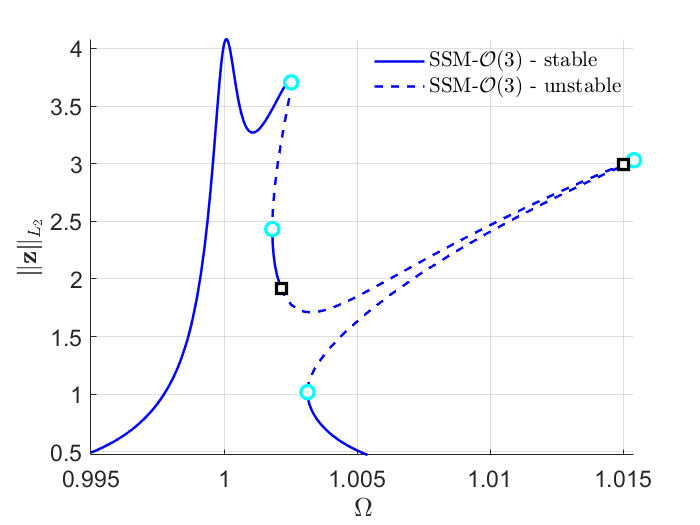

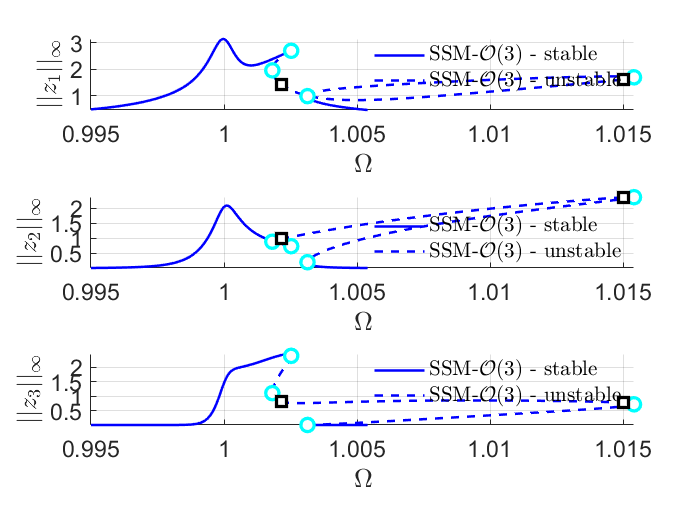

% plot results
f1 = figure('Name','Polar-Norm');
f2 = figure('Name',['Polar-Amplitude at DOFs ' num2str(outdof)]);
figs = [f1, f2];
plot_FRC_full(FRC_ep_polar,outdof,order,'freq','lines',figs,'blue')

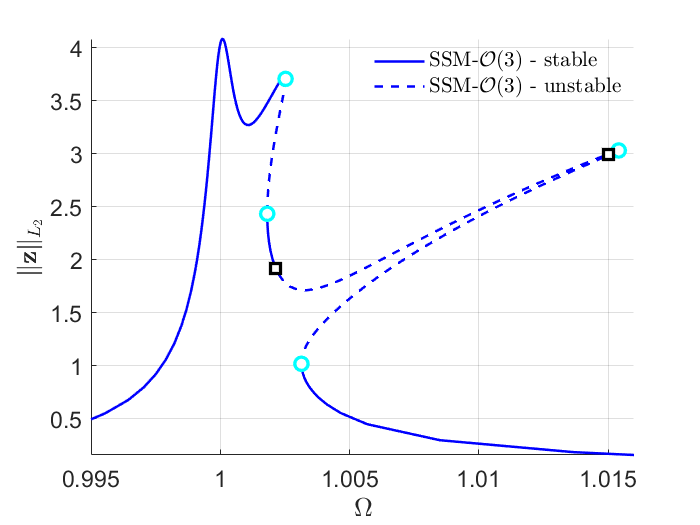

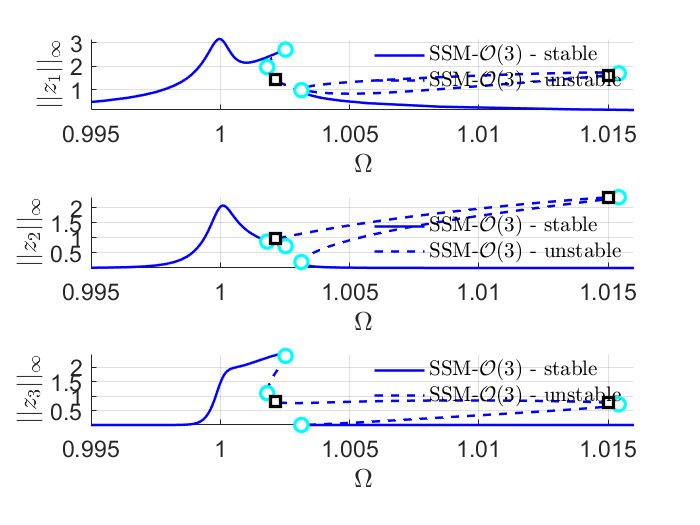


f3 = figure('Name','Cart-Norm');
f4 = figure('Name',['Cart-Amplitude at DOFs ' num2str(outdof)]);
figs = [f3, f4];
plot_FRC_full(FRC_ep_cart,outdof,order,'freq','lines',figs,'blue')

## Validation using COCO


 Run='FRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.00e-02  1.06e+01    0.0    0.0    0.0
   1   1  1.00e+00  5.51e-01  3.11e-04  1.06e+01    0.0    0.0    0.0
   2   1  1.00e+00  3.28e-01  5.04e-06  1.06e+01    0.0    0.0    0.0
   3   1  1.00e+00  2.39e-03  8.14e-10  1.06e+01    0.0    0.1    0.0
   4   1  1.00e+00  7.35e-07  1.81e-15  1.06e+01    0.0    0.1    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1         amp2         amp3
    0  00:00:00   1.0562e+01      1  EP      9.9697e-01   6.3023e+00   5.0000e-03   7.7455e-01   4.7293e-02   1.2789e-05
    5  00:00:02   9.8080e+00      2  EP      9.9500e-01   6.3148e+00   5.0000e-03   4.9155e-01   8.4633e-03   4.5087e-08

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps      

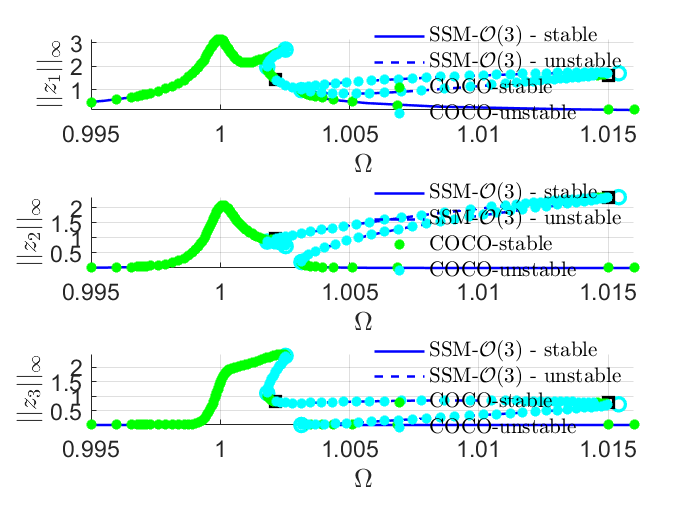

nCycles = 100;
coco = cocoWrapper(DS, nCycles, outdof);
set(coco.Options, 'PtMX', 500);
set(coco.Options, 'NAdapt', 1, 'h_max', 50);

startcoco = tic;
bd2 = coco.extract_FRC(freqRange);

timings.cocoFRC = toc(startcoco)

timings = struct with fields:
            MD: 0.0938
    epPolarFRC: 17.3371
     epCartFRC: 12.6190
       cocoFRC: 51.5635
